## Simulating colored noise

You have seen in [bivarnorm](matlab:open('./bivarnorm.mlx')) that a linear combination of independent random variables can be used to create correlated random variables. A digital filter produces a linear combination of an input sequence.

FIR filter: $y_k = b_1 x_k + b_2 x_{k-1} + \ldots + b_m x_{k-m}$

 It follows that passing a white noise input sequence, containing trial values from independent random variables, through a digital filter will create an output sequence that contains trial values from correlated random variables. The Power Spectral Density of the output sequence will not be a constant function of frequency, hence it will be a realization of a **colored noise** process.

To demonstrate the above, let us use the filter designed in [DSP/ firFiltDesignExample](matlab:open('../DSP/firFiltDesignExample.mlx')). 

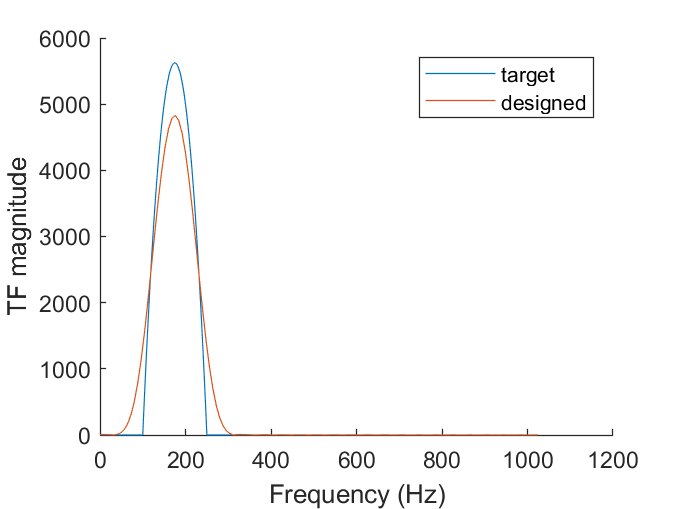

Minimum frequency 50 Hz
Maximum frequency 389.8584 Hz


addpath ../DSP
firFiltDesignExample;

close(qcFiltFig);
close(impFig);
close(trgtFig);

We generate a white noise sequence with each random variable having a Normal pdf.

nSamplesNoise = 10*fs; %number of samples desired 
wgnVec = randn(1,nSamplesNoise+fN);%#samples + FIR filter order

The sequence is filtered.

colNVecTmp = fftfilt(b,wgnVec);

Startup transient is dropped.

colNVec = colNVecTmp((fN+1):end);

Variance is normalized to be approximately unity.

colNVec = colNVec/std(colNVec);

Plot the realization of colored noise and compare with the input white noise sequence.

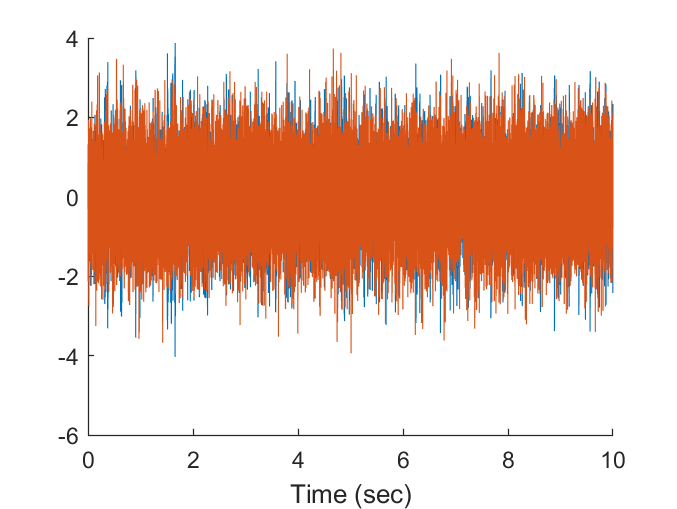

figure;
hold on;
noiseTimeVec = (0:(nSamplesNoise-1))/fs;
plot(noiseTimeVec, colNVec);
plot(noiseTimeVec, wgnVec((fN+1):end));
xlabel('Time (sec)');

Compare the estimated marginal pdfs of the two noise realizations.

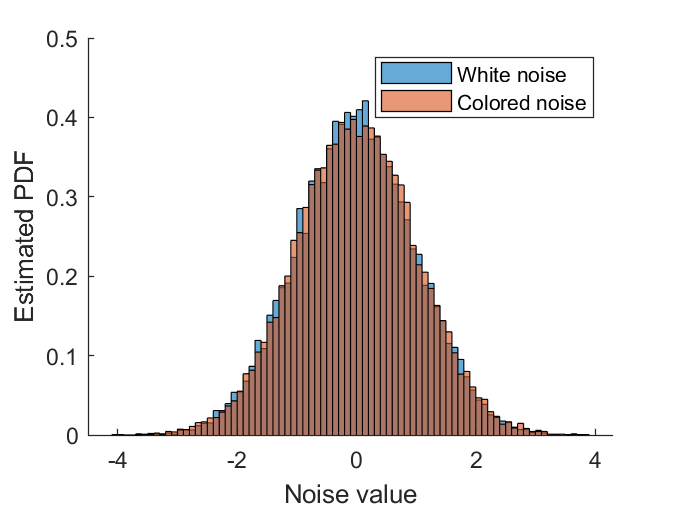

figure;
hold on;
histogram(wgnVec((fN+1):end),'Normalization','pdf');
histogram(colNVec,'Normalization','pdf');
xlabel('Noise value');
ylabel('Estimated PDF');
legend('White noise', 'Colored noise');

Compare the estimated bivariate pdfs for a given lag between the samples.

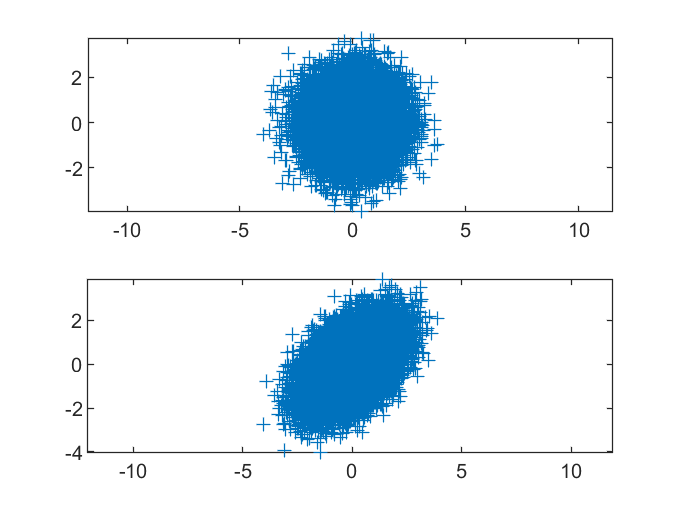

figure;
lag = 2; %samples
subplot(2,1,1);
plot(wgnVec(1:(end-lag)),wgnVec((1+lag):end),'+'); axis equal
subplot(2,1,2)
plot(colNVec(1:(end-lag)),colNVec((1+lag):end),'+'); axis equal